# ECSE 354 - Laboratory 1: Voltage and Current on a lossless transmission line

Group:

- Antoine Phan - 260948633

- Chenyi Xu - 260948311

## 1. Instantaneous forward and backward waves along a lossless transmission line

Task: Write 2 MATLAB functions that give instantaneous voltage and current for a forward wave and a backward wave on a lossless transmission line.

`[ vf if ]= forward_wave(v0,omega,phi,Z0,vp,z,t)`

`[ vb ib ]= backward_wave(v0,omega,phi,Z0,vp,z,t)`

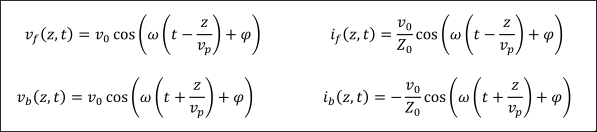

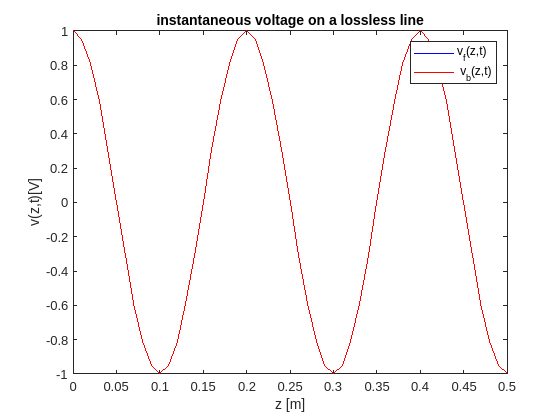

% help function;
% help zeros
function [v_f, i_f] = forward_wave(v0, omega, phi, Z0, vp, z, t)
    v_f = zeros(length(z), length(t));
    i_f = zeros(length(z), length(t));
    % v and i is a function of (z, t)
    for t_i=1:length(t)
        for z_j=1:length(z)
            v_f(z_j, t_i) = v0 * cos(omega*(t(t_i)-z(z_j)/vp) + phi);
            i_f(z_j, t_i) = v0/Z0 * cos(omega*(t(t_i)-z(z_j)/vp) + phi);
        end
    end
end

function [v_b, i_b] = backward_wave(v0, omega, phi, Z0, vp, z, t)
    v_b = zeros(length(z), length(t));
    i_b = zeros(length(z), length(t));
    % v and i is a function of (z, t)
    for t_i=1:length(t)
        for z_j=1:length(z)
            v_b(z_j, t_i) = v0 * cos(omega*(t(t_i) + z(z_j)/vp) + phi);
            i_b(z_j, t_i) = - v0/Z0 * cos(omega*(t(t_i) + z(z_j)/vp) + phi);
        end
    end
end

## 2. Movie of a forward wave and a backward wave

v0 = 1; % V
omega = 2*pi*10^9; % Hz
phi = 0; % rad
Z0 = 50; % Ohm
vp = 2e8; % m/s

z = 0:1e-2:5e-1; % m
t = 0:5e-11:5e-9; % s

[ v_f, i_f ]= forward_wave(v0, omega, phi, Z0, vp, z, t);
[ v_b, i_b ]= backward_wave(v0,omega,phi,Z0,vp,z,t);


For the forward and backward **voltage **movie

for k=1:length(t)
    plot(z, v_f(:,k),'b'); hold on;
    plot(z, v_b(:,k),'r'); hold off;
    xlabel('z [m]');
    ylabel('v(z,t)[V]');
    title('instantaneous voltage on a lossless line');
    legend('v_f(z,t)',' v_b(z,t)');
    axis([0 0.5 -1 1]);
    M_voltage_fb(k)=getframe;
end

movie2gif(M_voltage_fb, 'wave_voltage_fb.gif');
movie(M_voltage_fb);

For the forward and backward **current** movie:

for k=1:length(t)
    plot(z, i_f(:,k),'b'); hold on;
    plot(z, i_b(:,k),'r'); hold off;

v_s =     2.0000    1.9021    1.6180    1.1756    0.6180   -0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180   -0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021   -2.0000   -1.9021   -1.6180   -1.1756   -0.6180    0.0000    0.6180    1.1756    1.6180    1.9021    2.0000    1.9021    1.6180    1.1756    0.6180    0.0000   -0.6180   -1.1756   -1.6180   -1.9021
    1.9021    1.8090    1.5388    1.1180    0.5878    0.0000   -0.5878   -1.1180   -1.5388   -1.8090   -1.9021   -1.8090   -1.5388   -1.1180   -0.5878   -0.0000    0.5878    1.1180    1.5388    1.8090    1.9021    1.8090    1.5388    1.1180    0.5878    0.0000   -0.5878   -1.1180   -1.5388   -1.8090   -1.9021   -1.8090   -1.5388   -1.1180   -0.5878    0.0000    0.5878    1.1180    1.5388    1.8090    1.9021    1.8090    1.5388    1.1180    0.5878    0.0000   -0.5878   -1.1180   -1.5388   

    xlabel('z [m]');

i_s =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0038    0.0073    0.0100    0.0118    0.0124    0.0118    0.0100    0.0073    0.0038         0   -0.0038   -0.0073   -0.0100   -0.0118   -0.0124   -0.0118   -0.0100   -0.0073   -0.0038    0.0000    0.0038    0.0073    0.0100    0.0118    0.0124    0.0118    0.0100    0.0073    0.0038    0.0000   -0.0038   -0.0073   -0.0100   -0.0118   -0.0124   -0.0118   -0.0100   -0.0073   -0.0038    0.0000    0.0038    0.0073    0.0100    0.0118    0.0124    0.0118    0.0100    0.0073   

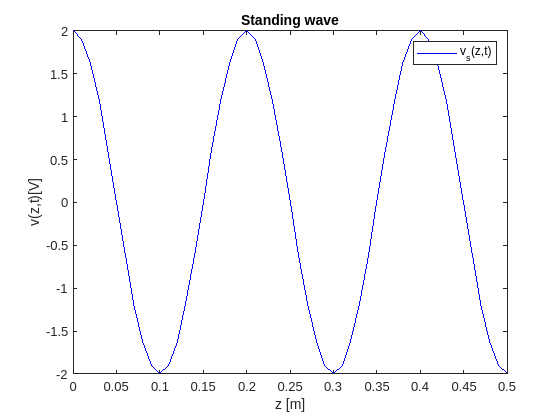

    ylabel('i(z,t)[A]');
    title('instantaneous current on a lossless line');
    legend('i_f(z,t)',' i_b(z,t)');
    axis([0 0.5 -0.02 0.02]);
    M_current_fb(k)=getframe;
end

movie2gif(M_current_fb, 'wave_current_fb.gif');
movie(M_current_fb);

## 3. Movie of a standing wave

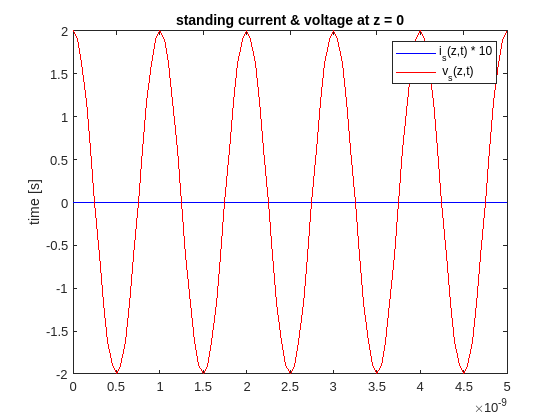

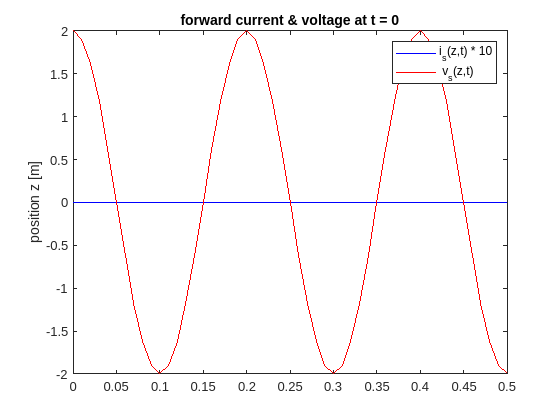

v0 = 1; % V

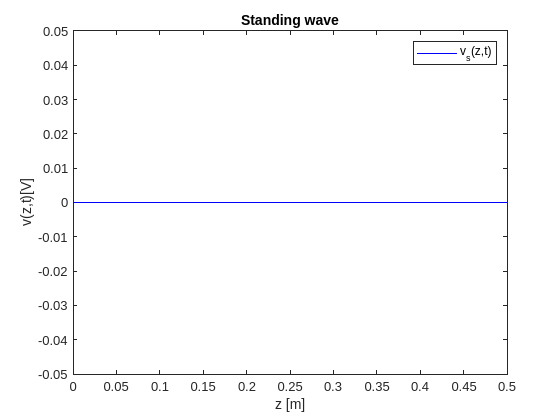

omega = 2*pi*10^9; % Hz
phi = 0; % rad
Z0 = 50; % Ohm
vp = 2e8; % m/s

z = 0:1e-2:5e-1; % [0, 0.4] m
t = 0:5e-11:5e-9; % [0, 5e-9] s

[ v_f, i_f ]= forward_wave(v0, omega, phi, Z0, vp, z, t);
[ v_b, i_b ]= backward_wave(v0, omega, phi, Z0, vp, z, t);


v_s = v_f + v_b
i_s = i_f + i_b

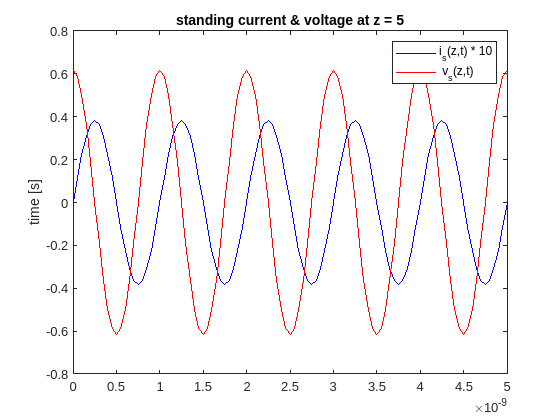

for k=1:length(t)
    plot(z, v_s(:,k),'b');
    xlabel('z [m]');
    ylabel('v(z,t)[V]');
    title('Standing wave');
    legend('v_s(z,t)');
    axis([0 0.5 -2 2]);
    M_v_stand(k)=getframe;

end
movie2gif(M_v_stand, 'wave_voltage_standing.gif')

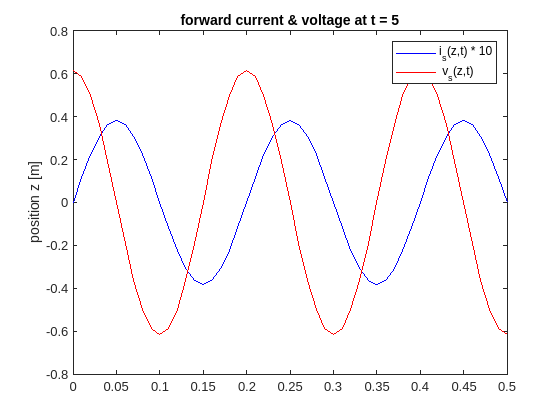

for k=1:length(t)
    plot(z, i_s(:,k),'b');
    xlabel('z [m]');
    ylabel('v(z,t)[V]');
    title('Standing wave');
    legend('v_s(z,t)');
    axis([0 0.5 -0.05 0.05]);
    M_i_stand(k)=getframe;

end
movie2gif(M_i_stand, 'wave_current_standing.gif')

Do the maxima in voltage and maxima in current occur at the same positions z ? YES!

random_z_idx = 5;
figure;
plot(t, i_s(random_z_idx,:) * 10,'b'); hold on;
plot(t, v_s(random_z_idx,:),'r'); hold off;
% xlabel('z [m]');
ylabel('time [s]');
title(sprintf('standing current & voltage at z = %d', random_z_idx));
legend('i_s(z,t) * 10',' v_s(z,t)');
% axis([0 0.5 -0.02 0.02]);

Do the maxima in voltage and maxima in current occur at the same times t ?

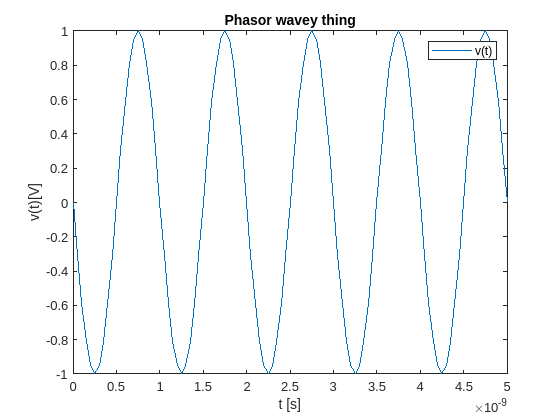

random_t_idx = 5;
figure;
plot(z, i_s(:,random_t_idx) * 10,'b'); hold on;
plot(z, v_s(:,random_t_idx),'r'); hold off;
% xlabel('z [m]');
ylabel('position z [m]');
title(sprintf('forward current & voltage at t = %d', random_t_idx));
legend('i_s(z,t) * 10',' v_s(z,t)');
% axis([0 0.5 -0.02 0.02]);

## 4. Phasor representation of waves

Write a MATLAB function that gives the instantaneous voltage v(t) of a the complex phasor representation V,

`[ v ] = ph2inst(V,omega,t)`

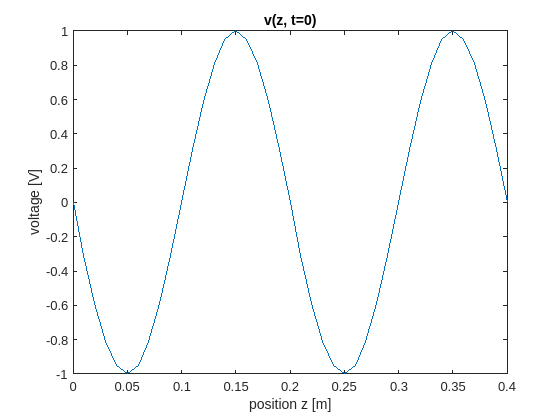

function [v] = ph2inst(V, omega, t)
    % (big, input) V is the phasor representation of v(z)
    % V = j exp( + j β z ) with β = (2π/0.20) rad/m
    % (small, output) v is a function of t
    v = zeros(length(V), length(t));

    for t_i=1:length(t)
        for z_idx=1:length(V)
            v(z_idx, t_i) =  real(V(z_idx)*exp(1i*omega*t(t_i)));

        end
    end
end

v0 = 1; % V
omega = 2*pi*10^9; % Hz
phi = 0; % rad
Z0 = 50; % Ohm
vp = 2e8; % m/s

z = 0:1e-2:4e-1; % [0, 0.4] m
t = 0:5e-11:5e-9; % [0, 5e-9] s

% Declare the phasor
beta = 2*pi/0.20;
V_z = 1i * exp(1i*beta*z);

v = ph2inst(V_z, omega, t);

for k=1:length(z)
    plot(t, v(k,:));
    xlabel('t [s]');
    ylabel('v(t)[V]');
    title('Phasor wavey thing');
    legend('v(t)');
    M_phasor(k)=getframe;
end
movie2gif(M_phasor, 'wave_phasor.gif')

### *Does the wave travel in the direction you expect?*

ANSWER: We expected the wave to travel backward, so **YES**

### Is the instantaneous voltage v(z,t = 0) what you expect?

plot(z, v(:,1)) % t = 0
xlabel('position z [m]')
ylabel('voltage [V]')
title('v(z, t=0)')

It starts at 90 degree (real part ~ cos axis), goes to negative maxima at 180 degree, and goes up. so **YES**

### Can you create a wave travelling in the opposite direction?

**YES**, by changing the sign inside the exponent of the phasor to get the forward wave